**TRAPEZ KURALIYLA SAYISAL İNTEGRAL HESAPLAMA**

Trapez kuralıyla belirli integral hesaplanıyor. 

Hesaplanacak fonksiyon : $f\left(x\right)=\sum_{n=0}^N {2x}^2$+ x -1

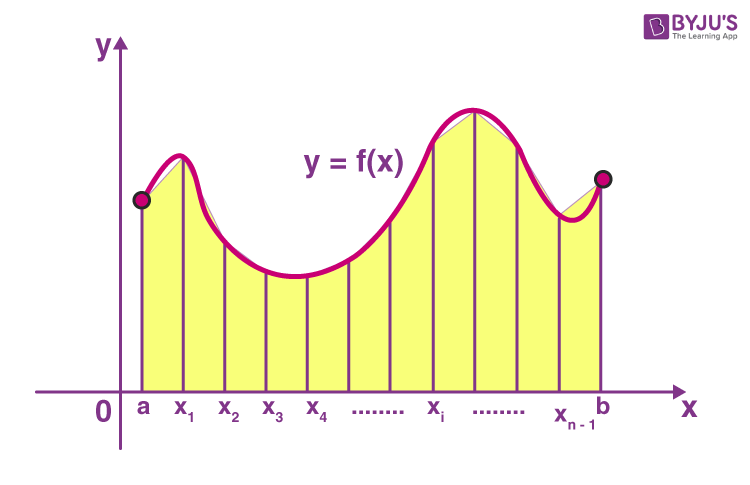

%%Trapez kuralıyla integral
clc

**Girdi parametreleri**

a=0;
b=2;
N=10; %%ayrıklaştırma parametresi sayısı

delta = (b-a)/N-1;
%% X = a:delta:b

X= linspace(a,b,N);

f_X = 2*X.^2 + X -1; 

%%döngü ile hesaplama

result = 0 ; 

for n=2:N-1
    result = result + f_X(n);
end
result = delta * (result + (f_X(1)+f_X(N))/2)